# Tracking a ballistic object on reentry

Reference: Beyond the Kalman Filter, B. Ristic, chapter 5

this simulation deals with tracking an object ( asteroid, satellite, missile... ) as it enters the Earth's atmosphere. Two simplifications: the radar's measurement model is not actually linear, and the asteroid is not likely to fall following a vertical trajectory, rather an angled one...

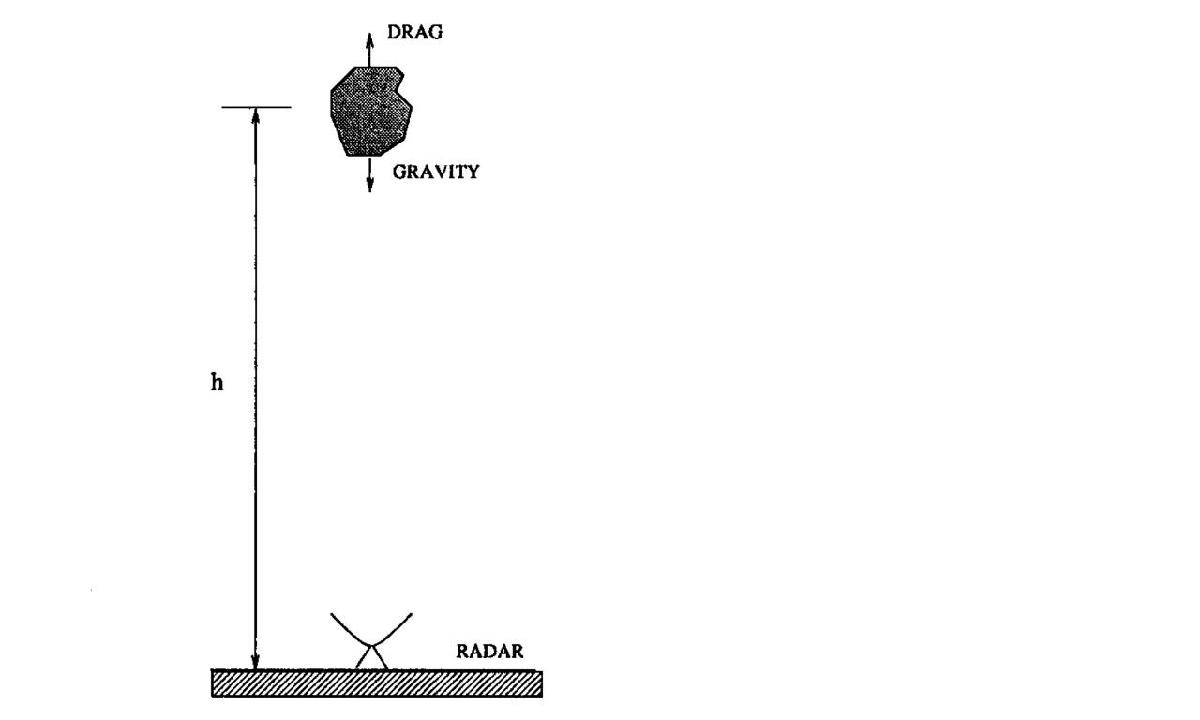

## Simulation parameters


N = 300;
x = zeros(3,N+1);

x(:,1) = [61e3 ; 3048; 19161];
tau = 0.1;
q1 = 0;
q2 = 0;
Q = [q1*tau*tau*tau/3, q1*tau*tau*0.5, 0;
     q1*tau*tau*0.5, q1*tau, 0;
     0 0 q2*tau];

y = zeros(1,N);
H = [1, 0, 0];
R = 200*200; % Sensor noise variance
T = tau; % Capital T is the sensor frequency



## Simulation


for i = 1 : N
    x(:,i+1) = f(x(:,i),tau) + mvnrnd([0 0 0]', Q)';
    y(:,i) = H*x(:,i) + sqrt(R)*randn();
end
x

x = 1.0e+04 *

    6.1000    6.0695    6.0390    6.0085    5.9780    5.9475    5.9170    5.8864    5.8559    5.8253    5.7948    5.7642    5.7336    5.7030    5.6724    5.6418    5.6112    5.5806    5.5500    5.5193    5.4887    5.4580    5.4273    5.3966    5.3660    5.3353    5.3046    5.2739    5.2431    5.2124    5.1817    5.1509    5.1202    5.0894    5.0586    5.0279    4.9971    4.9663    4.9355    4.9047    4.8739    4.8431    4.8122    4.7814    4.7506    4.7197    4.6889    4.6580    4.6271    4.5963
    0.3048    0.3049    0.3050    0.3051    0.3052    0.3053    0.3054    0.3054    0.3055    0.3056    0.3057    0.3058    0.3059    0.3060    0.3061    0.3062    0.3063    0.3063    0.3064    0.3065    0.3066    0.3067    0.3068    0.3069    0.3070    0.3070    0.3071    0.3072    0.3073    0.3074    0.3074    0.3075    0.3076    0.3077    0.3078    0.3078    0.3079    0.3080    0.3081    0.3081    0.3082    0.3083    0.3083    0.3084    0.3085    0.3085    0.3086    0.3086    

y

y = 1.0e+04 *

    6.1200    6.0376    6.0374    5.9841    6.0087    5.9311    5.9032    5.8434    5.8530    5.8002    5.8069    5.7721    5.7312    5.7114    5.6781    5.6560    5.6184    5.5471    5.5712    5.4837    5.4901    5.4807    5.4443    5.4195    5.3698    5.3827    5.3078    5.2827    5.2498    5.2293    5.1971    5.1580    5.1254    5.1005    5.0780    5.0212    4.9980    4.9766    4.9251    4.9022    4.8552    4.8175    4.8324    4.8021    4.7203    4.7249    4.7093    4.6490    4.6495    4.5937


## Plot noiseless trajectory + noisy sensor measurements

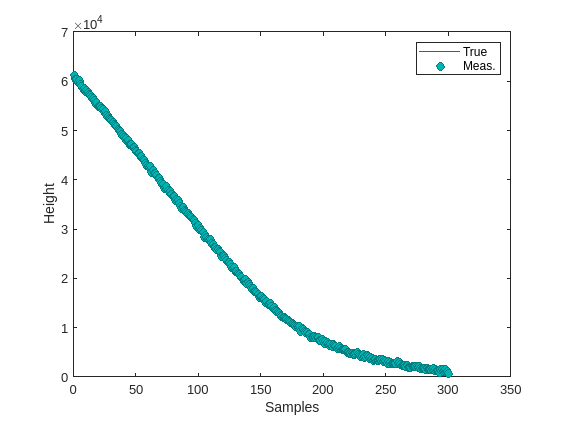


figure
plot(x(1,:))
xlabel("Samples")
ylabel("Height")
hold on;
scatter([1:1:N], y(1,:),'MarkerEdgeColor',[0 .5 .5],...
              'MarkerFaceColor',[0 .7 .7],...
              'LineWidth',0.2)
legend("True","Meas.")

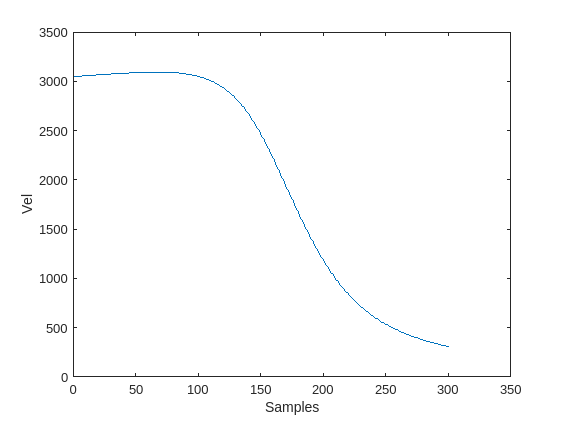


figure
plot(x(2,:))
xlabel("Samples")
ylabel("Vel")

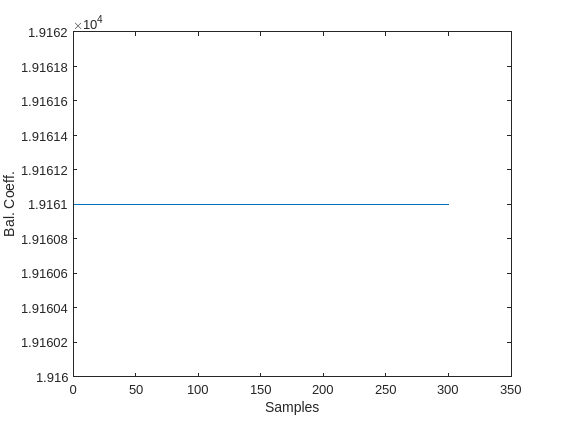


figure
plot(x(3,:))
xlabel("Samples")
ylabel("Bal. Coeff.")

## Initial variance of object


sigma_beta = 7184; % Variance of ballistic coeff.
P_0 = [R , R/tau , 0;
            R/tau , 2*R/(tau*tau) , 0;
            0 , 0 , sigma_beta*sigma_beta];


## CRLB (noiseless)

here we compute the Cramer Rao Lower Bound for the given samples

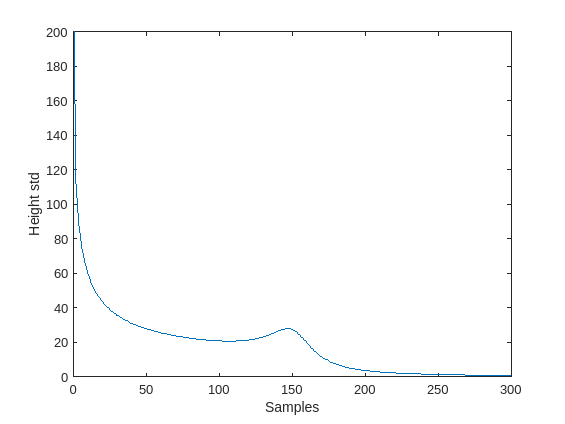

J = zeros(3,3,N);
J(:,:,1) = inv(P_0); % For gaussian densities the information matrix is the inverse of the cov. matrix
CRLB = zeros(3,3,N);
CRLB(:,:,1) = P(:,:,1);
cholCRLB = zeros(3,3,N);
cholCRLB(:,:,1) = chol(CRLB(:,:,1));

invR = inv(R);
g = 9.80665;
eta = 1.49e-4;

for i = 2 : N
    f21 = eta*g*p(x(1,i))*x(2,i)*x(2,i)/(2*x(3,i));
    f22 = g*p(x(1,i))*x(2,i)/x(3,i);
    f23 = g*p(x(1,i))*x(2,i)/(2*x(3,i)*x(3,i));
    Ftilde = [1, -tau, 0;
              f21*tau, 1-f22*tau, f23*tau;
              0, 0, 1];
    invFtilde = inv(Ftilde);
    J(:,:,i) = (H')*invR*H + (invFtilde')*J(:,:,i-1)*invFtilde;
    diagJ = diag(diag(J(:,:,i)));
    CRLB(:,:,i) = inv(diagJ);
    cholCRLB(:,:,i) = chol(CRLB(:,:,i));
end

% Now we plot the result


%plot. squeeze reshapes the vectors into columns rather than timeseries so i use transpose

figure
plot( squeeze(cholCRLB(1,1,:))' )
xlabel("Samples")
ylabel("Height std")

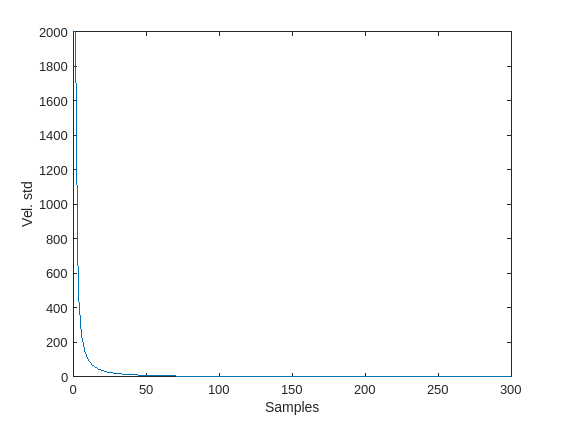


figure
plot( squeeze(cholCRLB(2,2,:))' )
xlabel("Samples")
ylabel("Vel. std")

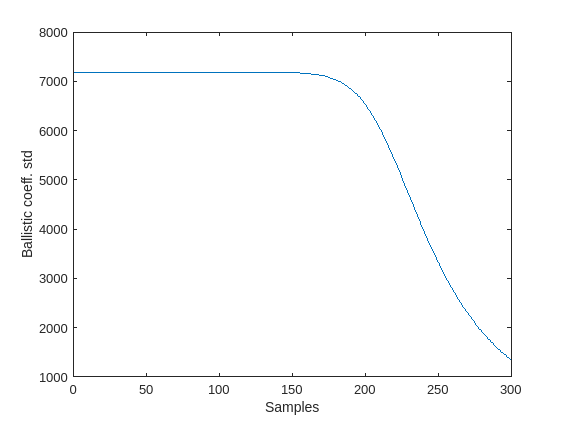


figure
plot( squeeze(cholCRLB(3,3,:))' )
xlabel("Samples")
ylabel("Ballistic coeff. std")

Remember that the CRLB constitutes a true lower bound only up to second order statistics. Neverthless, it's still a useful benchmark

#### CRLB (Noisy)

here we vary the process noise.

This is the recursion in the presence of process noise

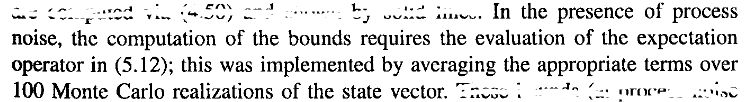

We wish to create two timeseries:

1)Matrix Timeseries of Ftilde over time. 

2)Matrix Timeseries of the product (Ftilde')QFtilde over time

q1 = 5;
q2 = 5; % Change the amount of noise
Q = [q1*tau*tau*tau/3, q1*tau*tau*0.5, 0;
     q1*tau*tau*0.5, q1*tau, 0;
     0 0 q2*tau];

x = zeros(3,N+1);
x(:,1) = [61e3 ; 3048; 19161];

M = 100; % This is the number of monte carlo runs
FtildeS = zeros(3,3,N,M);
FtinvQFS = zeros(3,3,N,M);


invQ = inv(Q);

for j = 1 : M
    x(:,1) = [61e3 ; 3048; 19161]; % Reset the initial condition
    for i = 1 : N
            f21 = eta*g*p(x(1,i))*x(2,i)*x(2,i)/(2*x(3,i));
            f22 = g*p(x(1,i))*x(2,i)/x(3,i);
            f23 = g*p(x(1,i))*x(2,i)/(2*x(3,i)*x(3,i));
            Ftilde = [ 1, -tau, 0;
                       f21*tau, 1-f22*tau, f23*tau;
                       0, 0, 1]; 
            FtildeS(:,:,i,j) = Ftilde;
            FtinvQFS(:,:,i,j) = (Ftilde')*invQ*Ftilde;
            x(:,i+1) = f(x(:,i),tau) + mvnrnd([0 0 0]', Q)'; % Compute nxt variable
    end
end


% Now we have to compute the noisy CRLB. Take the same code we used before,
% but now we have precomputed the gradient

J = zeros(3,3,N);
J(:,:,1) = inv(P_0); % For gaussian densities the information matrix is the inverse of the cov. matrix

noiselessCholCRLB = cholCRLB; % Save noiselss result

CRLB = zeros(3,3,N);
CRLB(:,:,1) = P(:,:,1);
cholCRLB = zeros(3,3,N);
cholCRLB(:,:,1) = chol(CRLB(:,:,1));

% ev before the variable name stands for "expected value". We evaluate it
% in the following way:
% 1) First, consider the kth column of the 3rd dimension, that is where we have stored
% the evaluations related to the kth time for all the runs
% 2) Then, sum columnwise on the 4th dimension, that is the sample space,
% and average by M



    

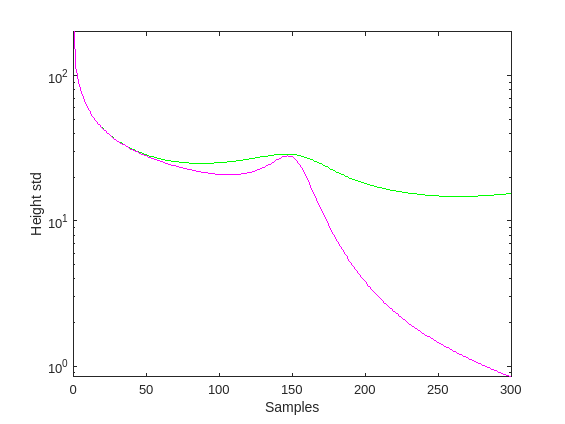

for k = 2 : N 
    %
      evFtilde = zeros(3,3);
      evFtinvQFS =  zeros(3,3); % Reset the sum
            for j = 1 : M
               evFtilde = evFtilde + FtildeS(:,:,k,j);
               evFtinvQFS =  evFtinvQFS + FtinvQFS(:,:,k,j) ;
            end
            evFtilde = evFtilde/M;
            evFtinvQFS = evFtinvQFS/M;
   %
    J(:,:,k) = invQ + (H')*invR*H - invQ*evFtilde*inv(evFtinvQFS + J(:,:,k-1) )*(evFtilde')*invQ; % This looks 
    diagJ = diag(diag(J(:,:,k)));
    CRLB(:,:,k) = inv(diagJ);
    cholCRLB(:,:,k) = chol(CRLB(:,:,k));
end


figure
semilogy( squeeze(cholCRLB(1,1,:))'  , "green")
xlabel("Samples")
ylabel("Height std")
hold on
semilogy( squeeze(noiselessCholCRLB(1,1,:))' , "magenta" )

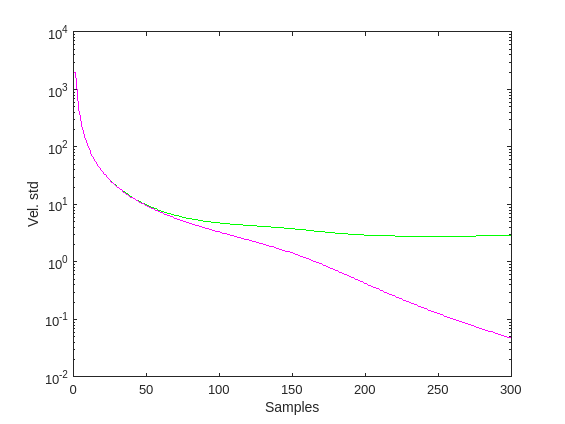



figure
semilogy( squeeze(cholCRLB(2,2,:))',"green")
xlabel("Samples")
ylabel("Vel. std")
hold on
semilogy( squeeze(noiselessCholCRLB(2,2,:))' , "magenta" )

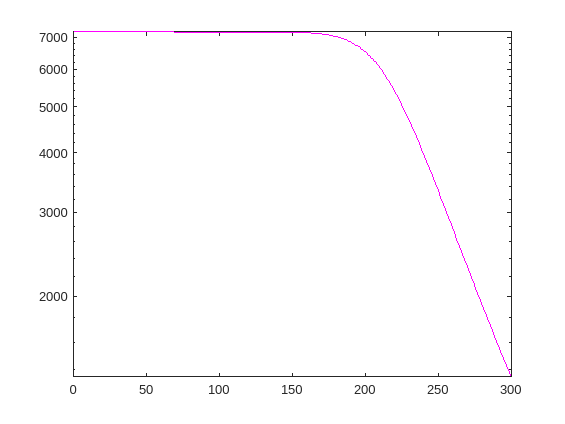


figure % This doesn't plot in log scale for some  reason ?????????
semilogy( squeeze(cholCRLB(3,3,:))', "green"  )
xlabel("Samples")
ylabel("Ballistic coeff. std")
hold on
semilogy( squeeze(noiselessCholCRLB(3,3,:))' ,  "magenta" )

# Estimation algorithms

Regenerate a target state trajectory once more. Then we declare the covariance for whichever state estimate we might apply afterwards

for i = 1 : N
    x(:,i+1) = f(x(:,i),tau) + mvnrnd([0 0 0]', Q)';
    y(:,i) = H*x(:,i) + sqrt(R)*randn();
end
x

x = 1.0e+04 *

    6.1000    6.0695    6.0390    6.0085    5.9780    5.9475    5.9170    5.8864    5.8559    5.8253    5.7948    5.7642    5.7336    5.7030    5.6724    5.6417    5.6111    5.5804    5.5498    5.5191    5.4884    5.4577    5.4270    5.3963    5.3655    5.3348    5.3041    5.2733    5.2426    5.2118    5.1810    5.1502    5.1194    5.0886    5.0578    5.0269    4.9961    4.9652    4.9344    4.9035    4.8726    4.8418    4.8109    4.7800    4.7491    4.7182    4.6873    4.6564    4.6254    4.5945
    0.3048    0.3049    0.3049    0.3050    0.3053    0.3054    0.3055    0.3054    0.3055    0.3056    0.3058    0.3060    0.3061    0.3063    0.3064    0.3066    0.3066    0.3067    0.3068    0.3069    0.3069    0.3071    0.3071    0.3073    0.3073    0.3074    0.3075    0.3077    0.3078    0.3079    0.3079    0.3080    0.3081    0.3082    0.3083    0.3085    0.3086    0.3086    0.3086    0.3087    0.3088    0.3088    0.3088    0.3090    0.3090    0.3092    0.3093    0.3093    

y

y = 1.0e+04 *

    6.0860    6.0734    6.0233    6.0465    5.9955    5.9341    5.9106    5.8594    5.8427    5.8035    5.7898    5.7496    5.7239    5.6908    5.6291    5.6399    5.6001    5.5463    5.5388    5.5343    5.5015    5.4365    5.4211    5.3397    5.3663    5.2975    5.2786    5.2787    5.2393    5.1998    5.1644    5.1656    5.0947    5.1199    5.0238    5.0267    5.0059    4.9942    4.9435    4.9312    4.9038    4.8069    4.8292    4.7605    4.7455    4.7102    4.6907    4.6784    4.6378    4.6052



P = zeros(3,3,N+1);
P(:,:,1) = P_0;


Functions

function [p_out] = p(h_in)
gamma = 1.754;
eta = 1.49e-4;
p_out = gamma*exp(-eta*h_in);
end
    
function [x_nxt] = f(x,tau)
%Constants
g = 9.80665;

h = x(1);
v = x(2);
beta = x(3);

p_h = p(h);

h_dot = -v;
v_dot = -(p_h*g*v*v)/(2*beta) + g;
beta_dot = 0;

x_nxt =  x + tau*[h_dot ; v_dot; beta_dot];

end
